wellID = 1;
numSeconds = 1;
resolution = 10;
samplingFrequency = 20000;
startSample = 1;
highPassCutOff = 1;
bandwidth = [270 1000];
correctionFactor = 2;

cellsMedia = '/home/mxwbio/Data/26/01/15_JG_Neurons/260115/P003375/ActivityScan/000002/data.raw.h5'

cellsMedia = '/home/mxwbio/Data/26/01/15_JG_Neurons/260115/P003375/ActivityScan/000002/data.raw.h5'

rawData_cellsMedia = mxw.fileManager(cellsMedia,wellID);

cellsT0 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260115/P003425/ActivityScan/000005/data.raw.h5'

cellsT0 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260115/P003425/ActivityScan/000005/data.raw.h5'

rawData_cellsT0 = mxw.fileManager(cellsT0,wellID);

cellsT30 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260115/P003375/ActivityScan/000007/data.raw.h5'

cellsT30 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260115/P003375/ActivityScan/000007/data.raw.h5'

rawData_cellsT30 = mxw.fileManager(cellsT30,wellID);

cellsT60 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260115/P003375/ActivityScan/000010/data.raw.h5'

cellsT60 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260115/P003375/ActivityScan/000010/data.raw.h5'

rawData_cellsT60 = mxw.fileManager(cellsT60,wellID);

cellsT120 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260115/P003375/ActivityScan/000018/data.raw.h5'

cellsT120 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260115/P003375/ActivityScan/000018/data.raw.h5'

rawData_cellsT120 = mxw.fileManager(cellsT120,wellID);

cellsH14 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260116/P003375/ActivityScan/000019/data.raw.h5'

cellsH14 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260116/P003375/ActivityScan/000019/data.raw.h5'

rawData_cellsH14 = mxw.fileManager(cellsH14,wellID);

cellsH14_5 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260116/P003375/ActivityScan/000023/data.raw.h5'

cellsH14_5 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260116/P003375/ActivityScan/000023/data.raw.h5'

rawData_cellsH14_5 = mxw.fileManager(cellsH14_5,wellID);

cellsH21= '/home/mxwbio/Data/26/01/15_JG_Neurons/260116/P003375/ActivityScan/000024/data.raw.h5'

cellsH21 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260116/P003375/ActivityScan/000024/data.raw.h5'

rawData_cellsH21 = mxw.fileManager(cellsH21,wellID);

cellsH48= '/home/mxwbio/Data/26/01/15_JG_Neurons/260117/P003375/ActivityScan/000030/data.raw.h5'

cellsH48 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260117/P003375/ActivityScan/000030/data.raw.h5'

rawData_cellsH48 = mxw.fileManager(cellsH48,wellID);

cellsH72= '/home/mxwbio/Data/26/01/15_JG_Neurons/260118/P003375/ActivityScan/000039/data.raw.h5'

cellsH72 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260118/P003375/ActivityScan/000039/data.raw.h5'

rawData_cellsH72 = mxw.fileManager(cellsH72,wellID);

cellsH144= '/home/mxwbio/Data/26/01/15_JG_Neurons/260121/P003425/ActivityScan/000054/data.raw.h5'

cellsH144 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260121/P003425/ActivityScan/000054/data.raw.h5'

rawData_cellsH144 = mxw.fileManager(cellsH144,wellID);

table_cellsMedia = createActivityScanTable(rawData_cellsMedia,startSample,numSeconds,correctionFactor);
table_cellsMedia = highPassFilterTraces(table_cellsMedia,highPassCutOff,samplingFrequency);
[table_cellsMedia, AvPSD_cellsMedia, Avfreq_cellsMedia] = calculatePSDs(table_cellsMedia,samplingFrequency,resolution);

[RMS_cellsMedia] = calculateAverageRMS(AvPSD_cellsMedia,Avfreq_cellsMedia,bandwidth,resolution);
disp(RMS_cellsMedia);

   1.1338e-06



table_cellsMedia = calculateRMSs(table_cellsMedia, bandwidth,resolution);
table_cellsMedia = calculateResistances(table_cellsMedia, bandwidth);
%table_cellsMedia = addSurfaceScanData(table_cellsMedia,surfaceScan_cellsMedia);

% [table_cellsT0,~,~,~,~] = runAnalysis(rawData_cellsT0,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cellsMedia,2);
% 
% [table_cellsT30,~,~,~,~] = runAnalysis(rawData_cellsT30,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cellsMedia,0.5);
% 
% [table_cellsT60,~,~,~,~] = runAnalysis(rawData_cellsT60,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cellsMedia,0.5);

[table_cellsT120,~,PSDT120,freq,~] = runAnalysis(rawData_cellsT120,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cellsMedia,2);

   1.1476e-06




[table_cellsH14,~,PSDH14,~,~] = runAnalysis(rawData_cellsH14,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cellsMedia,2);

   1.0321e-06




[table_cellsH14_5,~,PSDH14_5,~,~] = runAnalysis(rawData_cellsH14_5,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cellsMedia,2);

   1.1399e-06




[table_cellsH21,~,PSDTH21,~,~] = runAnalysis(rawData_cellsH21,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cellsMedia,2);

   1.1494e-06



[table_cellsH48,~,PSDH48,~,~] = runAnalysis(rawData_cellsH48,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cellsMedia,2);

   1.1485e-06



[table_cellsH72,~,PSDH72,~,~] = runAnalysis(rawData_cellsH72,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cellsMedia,2);

   1.1456e-06



[table_cellsH144,~,PSD144,~,~] = runAnalysis(rawData_cellsH144,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cellsMedia,0.5);

   1.1401e-06



% clf;
% loglog(freq,PSDT120);
% hold on;
% loglog(freq,PSDH14);
% hold off;
% hold on;
% loglog(freq,PSDH14_5);
% hold off;
% hold on;
% loglog(freq,PSDTH21);
% hold off;
% hold on;
% loglog(freq,PSDH48);
% hold off;
% 
% legend('1','2','3','4','5')
% 




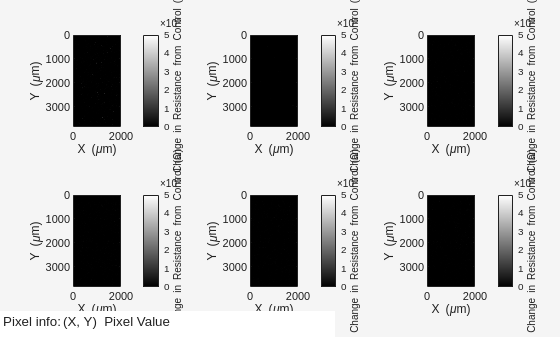

clf;
figure;
t = tiledlayout(2,3);

nexttile;

ax = gca;

Z = reshape(transpose(table_cellsT120.diffResistances),220,120);


imagesc(ax,table_cellsT120.xs,table_cellsT120.ys,Z);
impixelinfo;
axis(ax,'equal');
axis(ax,[0 2000 0 3850]);
colormap(ax,gray);
clim(ax,[0 500e3]);

xlabel(ax,'X (\mum)');
ylabel(ax,'Y (\mum)');

cb = colorbar(ax);
cb.Label.String = 'Change in Resistance from Control (\Omega)';
cb.Location = 'eastoutside';

nexttile;

ax = gca;

Z = reshape(transpose(table_cellsH14.diffResistances),220,120);

imagesc(ax,table_cellsH14.xs,table_cellsH14.ys,Z);
impixelinfo;
axis(ax,'equal');
axis(ax,[0 2000 0 3850]);
colormap(ax,gray);
clim(ax,[0 500e3]);

xlabel(ax,'X (\mum)');
ylabel(ax,'Y (\mum)');

cb = colorbar(ax);
cb.Label.String = 'Change in Resistance from Control (\Omega)';
cb.Location = 'eastoutside';

nexttile;

ax = gca;

Z = reshape(transpose(table_cellsH14_5.diffResistances),220,120);

imagesc(ax,table_cellsH14_5.xs,table_cellsH14_5.ys,Z);
impixelinfo;
axis(ax,'equal');
axis(ax,[0 2000 0 3850]);
colormap(ax,gray);
clim(ax,[0 500e3]);

xlabel(ax,'X (\mum)');
ylabel(ax,'Y (\mum)');

cb = colorbar(ax);
cb.Label.String = 'Change in Resistance from Control (\Omega)';
cb.Location = 'eastoutside';

nexttile;

ax = gca;

Z = reshape(transpose(table_cellsH21.diffResistances),220,120);

imagesc(ax,table_cellsH21.xs,table_cellsH21.ys,Z);
impixelinfo;
axis(ax,'equal');
axis(ax,[0 2000 0 3850]);
colormap(ax,gray);
clim(ax,[0 500e3]);

xlabel(ax,'X (\mum)');
ylabel(ax,'Y (\mum)');

cb = colorbar(ax);
cb.Label.String = 'Change in Resistance from Control (\Omega)';
cb.Location = 'eastoutside';

nexttile;

ax = gca;

Z = reshape(transpose(table_cellsH48.diffResistances),220,120);

imagesc(ax,table_cellsH48.xs,table_cellsH48.ys,Z);
impixelinfo;
axis(ax,'equal');
axis(ax,[0 2000 0 3850]);
colormap(ax,gray);
clim(ax,[0 500e3]);

xlabel(ax,'X (\mum)');
ylabel(ax,'Y (\mum)');

cb = colorbar(ax);
cb.Label.String = 'Change in Resistance from Control (\Omega)';
cb.Location = 'eastoutside';

nexttile;

ax = gca;

Z = reshape(transpose(table_cellsH144.diffResistances),220,120);

imagesc(ax,table_cellsH144.xs,table_cellsH144.ys,Z);
impixelinfo;
axis(ax,'equal');
axis(ax,[0 2000 0 3850]);
colormap(ax,gray);
clim(ax,[0 500e3]);

xlabel(ax,'X (\mum)');
ylabel(ax,'Y (\mum)');

cb = colorbar(ax);
cb.Label.String = 'Change in Resistance from Control (\Omega)';
cb.Location = 'eastoutside';

function T = createSerialRecordingTable(rawData,startSample,numSeconds,correctionFactor,recordingNum)
        

        numSamples = numSeconds*rawData.fileObj(1).samplingFreq;
        [electrodeNums, xs,ys] = calculateXYCoords(rawData);
        
        rawTraces = zeros(length(electrodeNums),numSamples);
        hasTraces = false(length(electrodeNums),1);

        T = table(electrodeNums,hasTraces,xs,ys,rawTraces);
        
        [rawTracesInScan,~,electrodesInScan] = rawData.extractRawData(startSample,numSamples,'file',recordingNum);
        electrodesInScan = transpose(cell2mat(electrodesInScan));

        rawTracesInScan = transpose((rawTracesInScan./(1E6))*correctionFactor);
        [inTable, location] = ismember(T.electrodeNums, electrodesInScan);
        T.rawTraces(inTable,:) = rawTracesInScan(location(inTable),:);
        T.hasTraces(inTable) = true;
     
end

function T = createActivityScanTable(rawData,startSample,numSeconds,correctionFactor)
        

        numSamples = numSeconds*rawData.fileObj(1).samplingFreq;
        [electrodeNums, xs,ys] = calculateXYCoords(rawData);
        
        rawTraces = zeros(length(electrodeNums),numSamples);
        hasTraces = false(length(electrodeNums),1);

        T = table(electrodeNums,hasTraces,xs,ys,rawTraces);
        
        n = rawData.nRecordings;

        for recordingNum = 1:n
            [rawTracesInScan,~,electrodesInScan] = rawData.extractRawData(startSample,numSamples,'file',recordingNum);
            electrodesInScan = transpose(cell2mat(electrodesInScan));

            rawTracesInScan = transpose((rawTracesInScan./(1E6))*correctionFactor);
            [inTable, location] = ismember(T.electrodeNums, electrodesInScan);
            T.rawTraces(inTable,:) = rawTracesInScan(location(inTable),:);
            T.hasTraces(inTable) = true;

        end
     
end




function T = createFullElectrodeTable(rawData)

           [electrodeNums, xs, ys] = calculateXYCoords(rawData);
           
           T = table(electrodeNums,xs,ys);
 
end

function T = addSurfaceScanData(T,scanT)

    scanT = sortrows(scanT);
    scanT = scanT(scanT.Var2 > 0 & scanT.Var2 <= 100,:);
    T = addvars(T,scanT.Var2,'NewVariableNames','surfaceScanVals');

end

function T = calculateDifferentialSurfaceScanData(T,scanT)

    scanT = sortrows(scanT);
    scanT = scanT(scanT.Var2 > 0 & scanT.Var2 <= 100,:);
    diffVals = T.surfaceScanVals - scanT.Var2;

    T = addvars(T,diffVals,'NewVariableNames','diffSurfaceScanVals');

end

    
function T = highPassFilterTraces(T, highPassCutOff,samplingFreq)
        
        [sos,g] = butter(1,highPassCutOff/(samplingFreq/2),"high");
        filteredTraces = filtfilt(sos,g,double(transpose(T.rawTraces)));
        T = addvars(T,transpose(filteredTraces),'NewVariableNames','filteredTraces');
        
end

function [T, avPSD, avFreq] = calculatePSDs(T,samplingFreq,resolution)
    
        

        overlap = 0;    
        nfft = samplingFreq / resolution;
        window = hann(nfft);

        [PSDs,frequencies] = pwelch(transpose(T.filteredTraces),window,overlap,nfft,samplingFreq);
        
        
        avPSD = sum(PSDs,2)/(sum(T.hasTraces)); 

        avFreq = frequencies;

        frequencies = repmat(frequencies,1,size(PSDs,2));
        PSDs = transpose(PSDs);
        frequencies = transpose(frequencies);

        T = addvars(T,PSDs,frequencies,'NewVariableNames',{'PSDs', 'frequencies'});  
        
end

function [T, avPSD, avFreq] = calculateSubsetPSDs(T,samplingFreq,resolution,numElectrodes)

        overlap = 0;    
        nfft = samplingFreq / resolution;
        window = hann(nfft);

        PSDs = zeros(height(T),((nfft/2)+1));
        frequencies = zeros(height(T),((nfft/2)+1));

        T = addvars(T,PSDs,frequencies,'NewVariableNames',{'PSDs', 'frequencies'});  

        electrodesCount = 0;
    
        for i=1:height(T)
            if (T.hasTraces(i)) && (electrodesCount <= numElectrodes)

                [T.PSDs(i,:),T.frequencies(i,:)] = pwelch(T.filteredTraces(i,:),window,overlap,nfft,samplingFreq);
                electrodesCount = electrodesCount + 1;
                frequencies = T.frequencies(i,:);
            end
        end

        avPSD = sum(T.PSDs,1)/numElectrodes; 

        avFreq = frequencies;

end




function [T,avDiffPSD] = calculateDifferentialPSDs (T,controlT)

        differentialPSDs = transpose(T.PSDs) - transpose(controlT.PSDs);

        avDiffPSD = sum(differentialPSDs,2)/sum(T.hasTraces);

        T = addvars(T, transpose(differentialPSDs), 'NewVariableNames','diffPSDs');
    
end

function avRMS = calculateAverageRMS(avPSD,avFreq,bandwidth, resolution)

        

        bandwidth = bandwidth./resolution;
        f = avFreq(bandwidth(1):bandwidth(2));
        PSD = avPSD(bandwidth(1):bandwidth(2));

        avRMS = sqrt(trapz(f,PSD));

end




function T = calculateRMSs(T,bandwidth,resolution)

        bandwidth = bandwidth./resolution;
        len = height(T);
        RMSs = zeros(len, 1);
        variances = zeros(len, 1);

        for i = 1:len
            f = transpose(T.frequencies(i,bandwidth(1):bandwidth(2)));
            PSD = transpose(T.PSDs(i,bandwidth(1):bandwidth(2)));
            RMSs(i) = sqrt(trapz(f,PSD)); 
            variances(i) = trapz(f,PSD); 
        end

        T = addvars(T, RMSs,variances,'NewVariableNames',{'RMSs','variances'});

end

function T = calculateDifferentialRMSs(T,bandwidth,resolution)

        bandwidth = bandwidth./resolution;
        len = height(T);
        diffVariances = zeros(len, 1);
        diffRMSs = zeros(len, 1);

        for i = 1:len
            f = transpose(T.frequencies(i,bandwidth(1):bandwidth(2)));
            diffPSD = transpose(T.diffPSDs(i,bandwidth(1):bandwidth(2)));
            diffRMSs(i) = sqrt(trapz(f,diffPSD)); 
            diffVariances(i) = trapz(f,diffPSD); 
        end

        T = addvars(T, diffRMSs,diffVariances, 'NewVariableNames',{'diffRMSs','diffVariances'});

end

function T = calculateResistances (T,bandwidth)
        
        boltzman = 1.38E-23;
        temp = 310;

        resistances = (transpose(T.variances))./(4*boltzman*temp*(bandwidth(2)-bandwidth(1)));
        T = addvars(T, transpose(resistances), 'NewVariableNames','resistances');

end


function T = calculateDifferentialResistances (T,bandwidth)
        
        boltzman = 1.38E-23;
        temp = 310;

        diffResistances = (transpose(T.diffVariances))./(4*boltzman*temp*(bandwidth(2)-bandwidth(1)));
        T = addvars(T, transpose(diffResistances), 'NewVariableNames','diffResistances');

end

function [electrodeNums, xs, ys] = calculateXYCoords(rawData)

        recordingElectrodes = rawData.processedMap.electrode();
        unroutedElectrodes = rawData.processedMap.nonRoutedElec();

        electrodeNums = cat(1,recordingElectrodes,unroutedElectrodes);
        electrodeNums = sort(electrodeNums);
        
        len = length(electrodeNums);
        
        xs = zeros(1,len);
        ys = zeros(1,len);
        
        for i = 1:len
            ys(i) = ceil(i/220) ;
            xs(i) = i - (220*(ys(i)-1));
            
        end

        W = 220; 

        x_rot = ys;
        y_rot = (W - 1) - xs;

        xs = x_rot;
        ys = y_rot;

       
        
        xs = transpose(xs*17.5);
        ys = transpose(ys*17.5);
end

function plotPowerSpectrum(cellsAvFreqArray,cellsAvPSDArray,tAvfreq,tAvPSD,nRecordings,endRecording,titlePlot,ylabelPlot)
        clf('reset');
        
        loglog(cellsAvFreqArray,sqrt(cellsAvPSDArray));
        hold on;
        loglog(tAvfreq,sqrt(tAvPSD));
        hold off;
        
        colorMapLength = nRecordings;
        red = [1,0,0];
        blue = [0,0,1];
        black = [0,0,0];
        
        
        colours_scale = [linspace(red(1),blue(1),colorMapLength)', linspace(red(2),blue(2),colorMapLength)', linspace(red(3),blue(3),colorMapLength)'];
        colours_ctrl = black;
        ax=gca;
        ax.ColorOrder = cat(1,colours_scale,colours_ctrl);
        
        hours = linspace(0,endRecording,nRecordings)+3;
        legendText = cell(1,nRecordings+1);
        
        for i = 1:nRecordings
            legendText{i} = sprintf('Hour %g ',hours(i));
        end
        
        mediaLabel = 'Media Control';
        legendText{nRecordings+1} = mediaLabel;
        legend(string(transpose(legendText)))
        
        xlim([0 5000]);
        xlabel('Frequency (Hz)');
        ylabel(ylabelPlot);
        title(titlePlot);
        set(gca,'xminorgrid','off','yminorgrid','off','xgrid','on','ygrid','on')
end

function plotPowerSpectrumDiff(cellsAvFreqArray,cellsAvPSDArray,nRecordings,endRecording,titlePlot,ylabelPlot)
        clf('reset');
        
        loglog(cellsAvFreqArray,cellsAvPSDArray);
        
        
        colorMapLength = nRecordings;
        red = [1,0,0];
        blue = [0,0,1];
        black = [0,0,0];
        
        
        colours_scale = [linspace(red(1),blue(1),colorMapLength)', linspace(red(2),blue(2),colorMapLength)', linspace(red(3),blue(3),colorMapLength)'];
        colours_ctrl = black;
        ax=gca;
        ax.ColorOrder = cat(1,colours_scale,colours_ctrl);
        
        hours = linspace(0,endRecording,nRecordings)+3;
        legendText = cell(1,nRecordings);
        
        for i = 1:nRecordings
            legendText{i} = sprintf('Hour %g ',hours(i));
        end
        
     
        legend(string(transpose(legendText)))
        
        xlim([100 3500]);
        xlabel('Frequency (Hz)');
        ylabel(ylabelPlot);
        title(titlePlot);
        set(gca,'xminorgrid','off','yminorgrid','off','xgrid','on','ygrid','on')
end

function generateMEAVideo(nRecordings,cellsTableArray,filename)
        videoFile = filename;
        
        v = VideoWriter(videoFile, 'Uncompressed AVI');
        v.FrameRate = 2;         
        open(v);
        
        figure;
        set(gcf,'Position',[100 100 700 900], 'Color','w');              
        ax = axes('Position',[0.1 0.1 0.75 0.8]);
        
        
        hours = 1.5;          
        
        for i = 1:nRecordings
        
            cla(ax);
        
            Z = reshape(transpose(cellsTableArray{i}.diffResistances),220,120);
        
            imagesc(ax,cellsTableArray{i}.xs,cellsTableArray{i}.ys,Z);
        
            axis(ax,'equal');
            axis(ax,[0 2000 0 3850]);
            colormap(ax,gray);
            clim(ax,[0 200e3]);
        
            xlabel(ax,'X (\mum)');
            ylabel(ax,'Y (\mum)');
                 
            cb = colorbar(ax);
            cb.Label.String = 'Change in Resistance from Control (\Omega)';
            cb.Location = 'eastoutside';
            
            t_hours = (i-1) * hours + 3;
            title(ax, sprintf('T = %.1f h', t_hours),'FontWeight','bold')
        
            drawnow        
            frame = getframe(gcf);
            writeVideo(v, frame);
        end
        
        close(v);
end

function [tableData, avPSD,avDiffPSD,avFreq,avRMS] = runAnalysis(rawData,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,controlTable,correctionFactor)

    tableData = createActivityScanTable(rawData, startSample,numSeconds,correctionFactor);
    tableData = highPassFilterTraces(tableData,highPassCutOff,samplingFrequency);
    
    [tableData, avPSD, avFreq] = calculatePSDs(tableData,samplingFrequency,resolution);
    [tableData,avDiffPSD] = calculateDifferentialPSDs(tableData,controlTable);
    
    tableData = calculateDifferentialRMSs(tableData, bandwidth,resolution);
    tableData = calculateDifferentialResistances(tableData, bandwidth);
    
    [avRMS] = calculateAverageRMS(avPSD,avFreq,bandwidth,resolution);
    disp(avRMS);
    
    tableData = calculateRMSs(tableData, bandwidth,resolution);
    tableData = calculateResistances(tableData, bandwidth);
    
    tableData = removevars(tableData,["rawTraces","filteredTraces",'PSDs','diffPSDs','frequencies']);

    %tableData = addSurfaceScanData(tableData,surfaceScan_cellsT60);
    %tableData = calculateDifferentialSurfaceScanData(tableData,surfaceScan_cellsMedia);
end